## MathTool HW6

## 2024-12-20

### Question 3 Classification (decision) in a 2-dimensional space

clear all; clc; close all;
addpath("hw6-files/");
load('fisherData.mat');

## Part a)

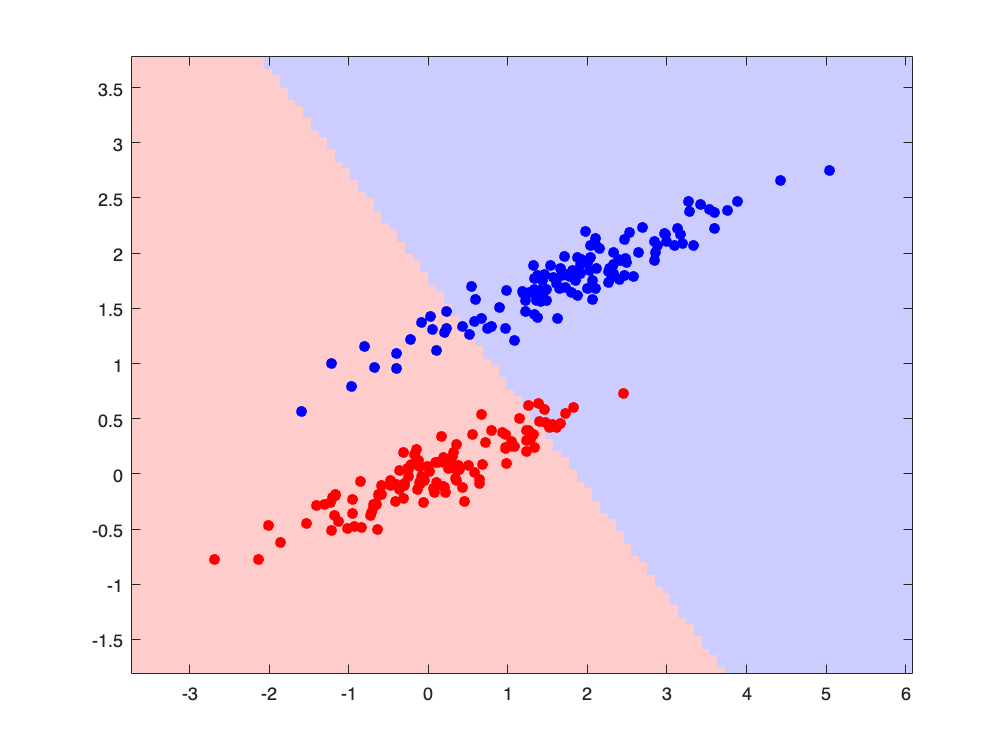

% Load the data
load fisherData.mat

%means and discriminant vector
mean1 = mean(data1, 1);
mean2 = mean(data2, 1);
discriminant = mean2 - mean1;
discriminant_unit = discriminant / norm(discriminant);

%for plotting
x_min = min([data1(:,1); data2(:,1)]) - 1;
x_max = max([data1(:,1); data2(:,1)]) + 1;
y_min = min([data1(:,2); data2(:,2)]) - 1;
y_max = max([data1(:,2); data2(:,2)]) + 1;
[x, y] = meshgrid(linspace(x_min, x_max, 100), linspace(y_min, y_max, 100));
grid_points = [x(:), y(:)];

%Gaussian likelihood
pdf1 = exp(-0.5 * sum((grid_points - mean1).^2, 2)) / (2 * pi);
pdf2 = exp(-0.5 * sum((grid_points - mean2).^2, 2)) / (2 * pi);
pdf1_image = reshape(pdf1, size(x));
pdf2_image = reshape(pdf2, size(x));

%do binary classification
binary_image = pdf2_image > pdf1_image;

figure;
imagesc([x_min, x_max], [y_min, y_max], binary_image);
set(gca, 'YDir', 'normal'); 
hold on;
scatter(data1(:,1), data1(:,2), 'r', 'filled');
scatter(data2(:,1), data2(:,2), 'b', 'filled');
colormap([1 0.8 0.8; 0.8 0.8 1]); 

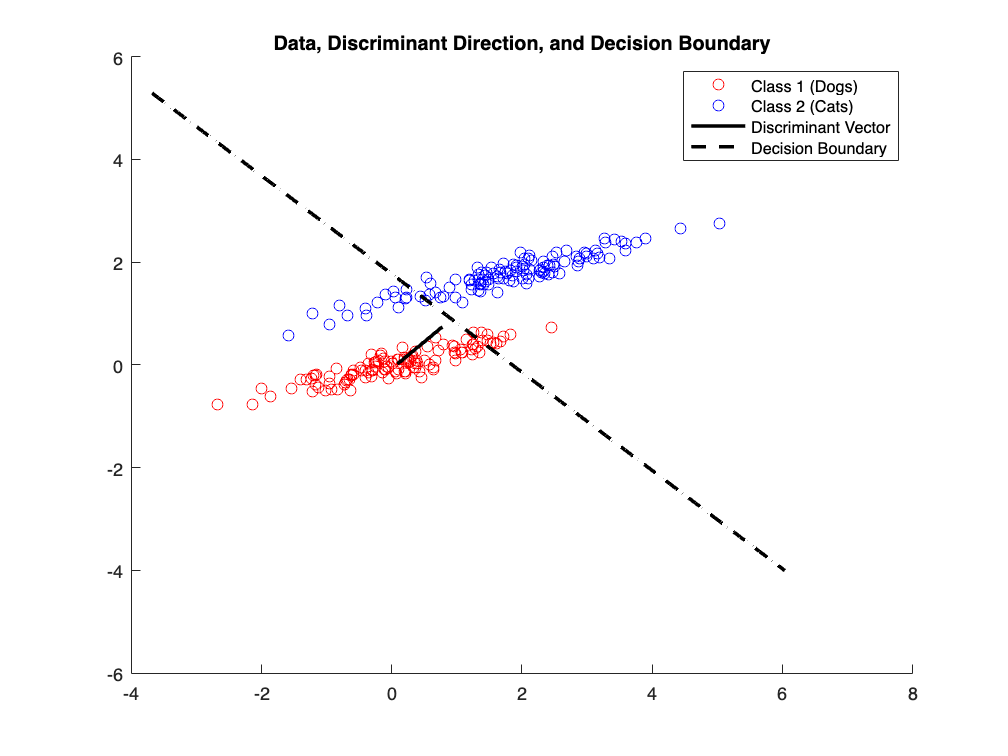

thresh = (sum(mean2.^2) - sum(mean1.^2)) / 2;
x_range = linspace(x_min, x_max, 100);
y_range = (thresh - discriminant(1) * x_range) / discriminant(2);
figure;
scatter(data1(:,1), data1(:,2), 'ro'); hold on;
scatter(data2(:,1), data2(:,2), 'bo');
plot([mean1(1), mean1(1) + discriminant_unit(1)], [mean1(2), mean1(2) + discriminant_unit(2)], 'k-', 'LineWidth', 2);
plot(x_range, y_range, 'k--', 'LineWidth', 2);
title('Data, Discriminant Direction, and Decision Boundary');
legend('Class 1 (Dogs)', 'Class 2 (Cats)', 'Discriminant Vector', 'Decision Boundary');

%calculate accuracy
proj_data1 = data1 * discriminant_unit';
proj_data2 = data2 * discriminant_unit';
threshold = (mean(proj_data1) + mean(proj_data2)) / 2;
correct1 = sum(proj_data1 < threshold);
correct2 = sum(proj_data2 > threshold);
accuracy = (correct1 + correct2) / (size(data1, 1) + size(data2, 1));
fprintf('Classification accuracy: %.2f%%\n', accuracy * 100);

Classification accuracy: 87.92%


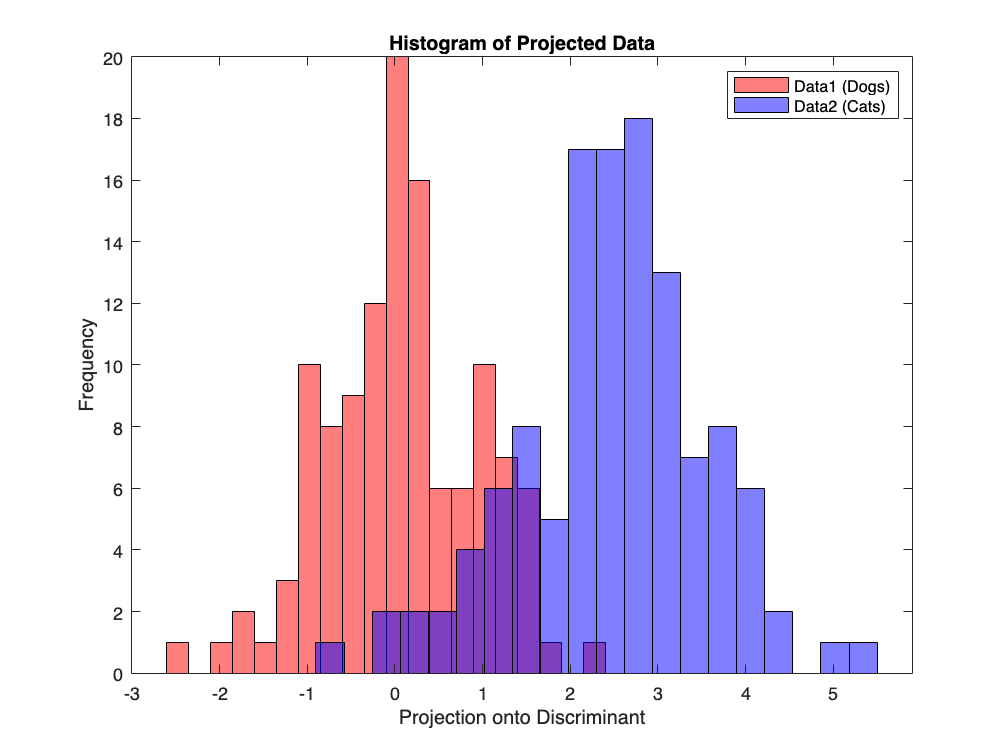

%histograms
figure;
histogram(proj_data1, 20, 'FaceColor', 'r', 'FaceAlpha', 0.5);
hold on;
histogram(proj_data2, 20, 'FaceColor', 'b', 'FaceAlpha', 0.5);
legend('Data1 (Dogs)', 'Data2 (Cats)');
xlabel('Projection onto Discriminant');
ylabel('Frequency');
title('Histogram of Projected Data');
hold off;

From the accuracy of classification, we can tell that 87.92% of the points are correctly classified by this classifier.

## Part b)

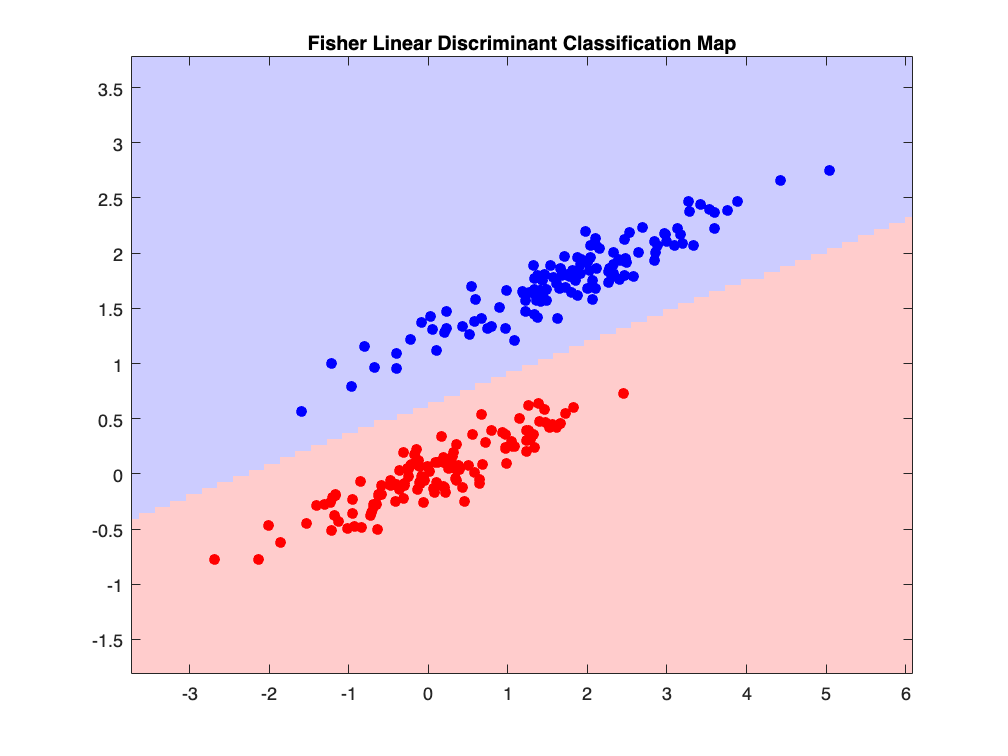

N1 = size(data1, 1);
N2 = size(data2, 1);

mean1 = mean(data1, 1);
mean2 = mean(data2, 1);

%calculate scatter matrix
S1 = cov(data1) * (size(data1, 1) - 1); 
S2 = cov(data2) * (size(data2, 1) - 1);
Sw = S1 + S2; %within-class scatter matrix

% Fisher's Linear Discriminant
diff_means = (mean2 - mean1)';
discriminant = Sw \ diff_means; %inv(Sw) * (mean2 - mean1)
discriminant_unit = discriminant / norm(discriminant);

x_min = min([data1(:,1); data2(:,1)]) - 1;
x_max = max([data1(:,1); data2(:,1)]) + 1;
y_min = min([data1(:,2); data2(:,2)]) - 1;
y_max = max([data1(:,2); data2(:,2)]) + 1;
[x, y] = meshgrid(linspace(x_min, x_max, 100), linspace(y_min, y_max, 100));
grid_points = [x(:), y(:)];

projections = grid_points * discriminant;
threshold = 0.5 * (mean1 * discriminant + mean2 * discriminant); %b
binary_image = reshape(projections > threshold, size(x));

figure;
imagesc([x_min, x_max], [y_min, y_max], binary_image);
set(gca, 'YDir', 'normal'); 
hold on;
scatter(data1(:,1), data1(:,2), 'r', 'filled');
scatter(data2(:,1), data2(:,2), 'b', 'filled');
colormap([1 0.8 0.8; 0.8 0.8 1]); 
title('Fisher Linear Discriminant Classification Map');

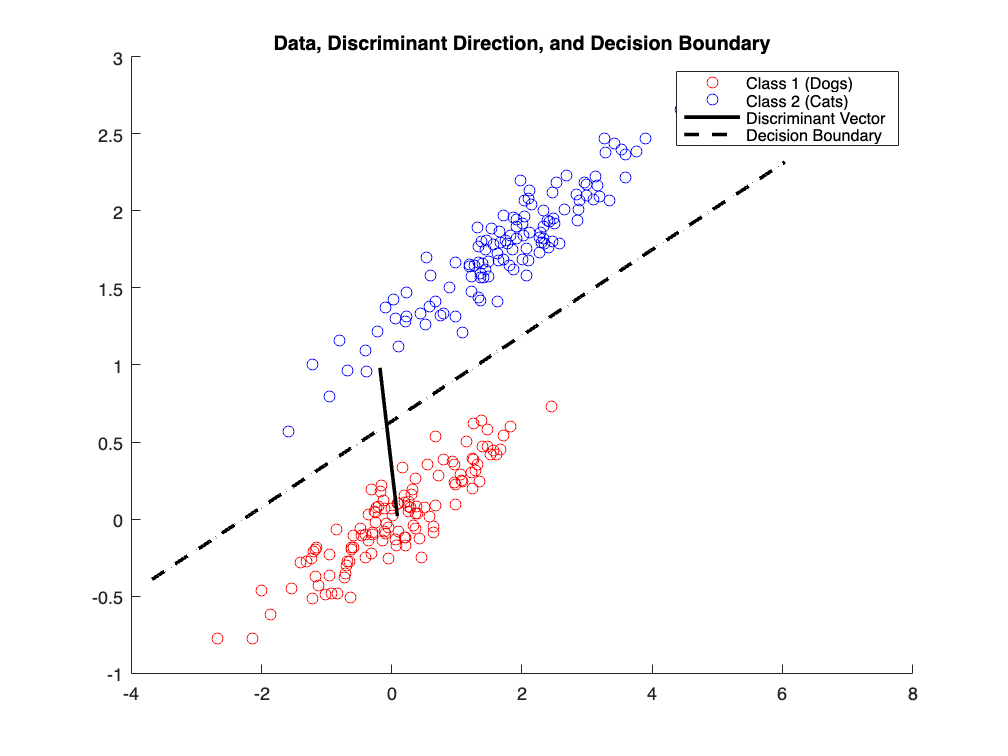


x_range = linspace(x_min, x_max, 100);
y_range = (threshold - discriminant(1) * x_range) / discriminant(2);
figure;
scatter(data1(:,1), data1(:,2), 'ro'); hold on;
scatter(data2(:,1), data2(:,2), 'bo');
plot([mean1(1), mean1(1) + discriminant_unit(1)], [mean1(2), mean1(2) + discriminant_unit(2)], 'k-', 'LineWidth', 2);
plot(x_range, y_range, 'k--', 'LineWidth', 2);
title('Data, Discriminant Direction, and Decision Boundary');
legend('Class 1 (Dogs)', 'Class 2 (Cats)', 'Discriminant Vector', 'Decision Boundary');

proj_data1 = data1 * discriminant;
proj_data2 = data2 * discriminant;
correct1 = sum(proj_data1 < threshold); %go to class 1
correct2 = sum(proj_data2 > threshold); %go to class 2
accuracy = (correct1 + correct2) / (size(data1, 1) + size(data2, 1));
fprintf('Classification accuracy using FLD: %.2f%%\n', accuracy * 100);

Classification accuracy using FLD: 100.00%


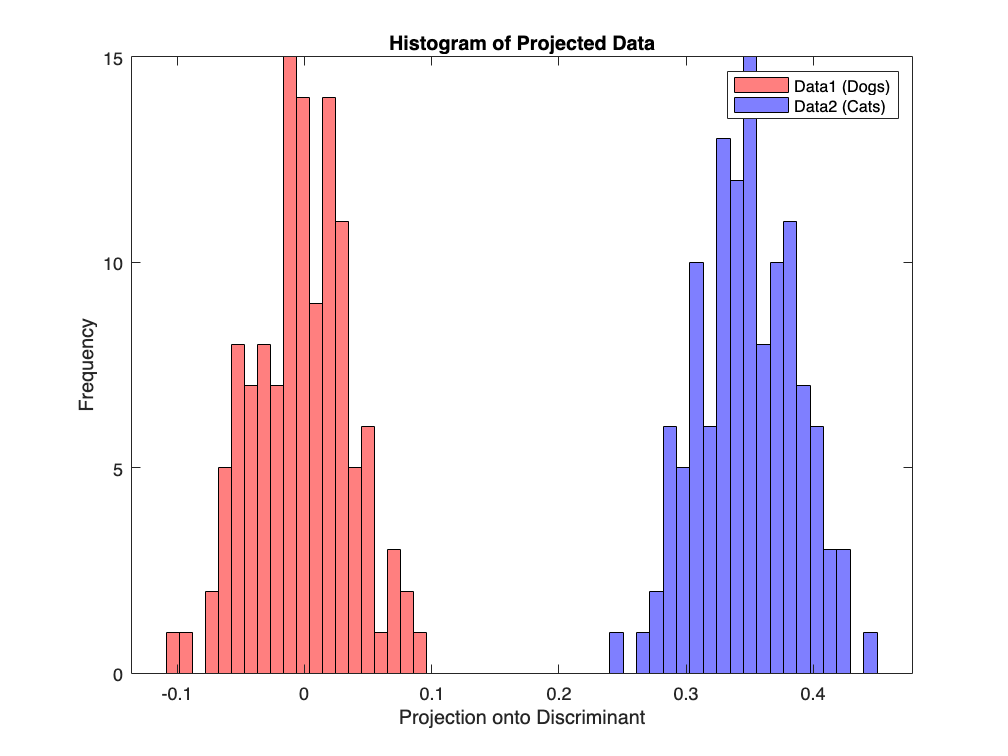

figure;
histogram(proj_data1, 20, 'FaceColor', 'r', 'FaceAlpha', 0.5);
hold on;
histogram(proj_data2, 20, 'FaceColor', 'b', 'FaceAlpha', 0.5);
legend('Data1 (Dogs)', 'Data2 (Cats)');
xlabel('Projection onto Discriminant');
ylabel('Frequency');
title('Histogram of Projected Data');
hold off;

## Part b) using SVD

pooledCovariance = ((N1 - 1) * S1 + (N2 - 1) * S2) / (N1 + N2 - 2);
[U, S, V] = svd(pooledCovariance);
S_inv = diag(1 ./ diag(S));
discriminant_svd = (V * S_inv * U') * diff_means;
discriminant_svd = discriminant_svd';
discriminant_unit = discriminant_svd / norm(discriminant_svd);
x1 = (V * S_inv * U') * mean1';
x2 = (V * S_inv * U') * mean2'; 
threshold_svd = (mean2 * x2 - mean1 * x1) / 2;

x_min = min([data1(:, 1); data2(:, 1)]) - 0.5;
x_max = max([data1(:, 1); data2(:, 1)]) + 0.5;
y_min = min([data1(:, 2); data2(:, 2)]) - 0.5;
y_max = max([data1(:, 2); data2(:, 2)]) + 0.5;
[X, Y] = meshgrid(linspace(x_min, x_max, 200), linspace(y_min, y_max, 200));
grid_points = [X(:), Y(:)];

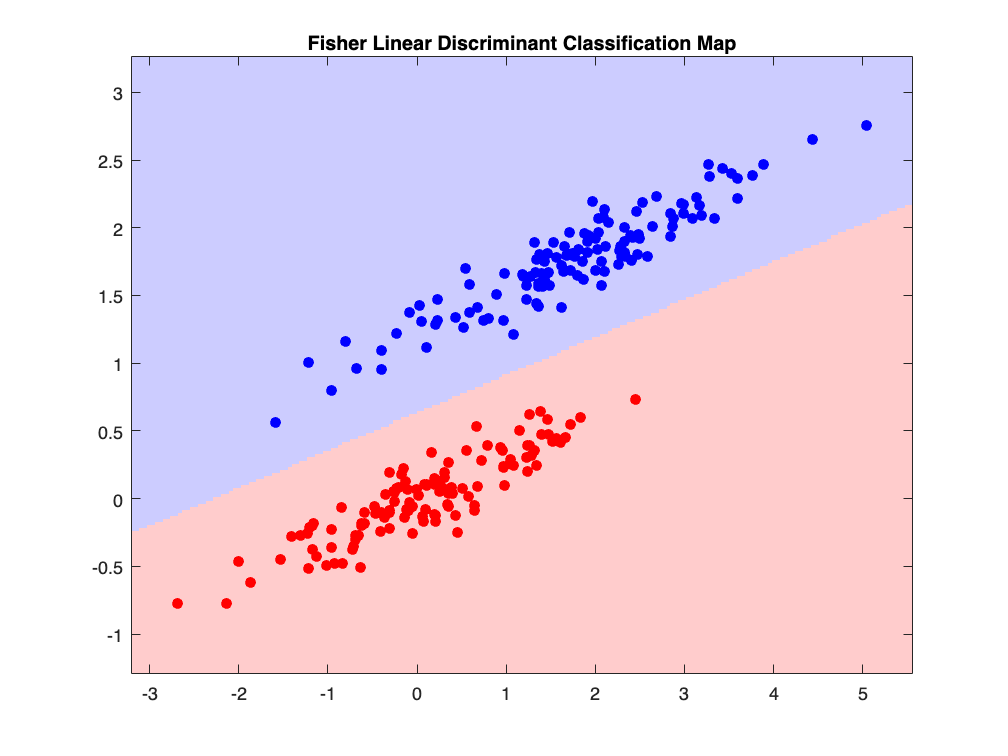

invPooledCov = V * S_inv * U'; 
constant = 1 / (2 * pi * sqrt(det(pooledCovariance))); 
pdf1 = constant * exp(-0.5 * sum((grid_points - mean1) * invPooledCov .* (grid_points - mean1), 2));
pdf2 = constant * exp(-0.5 * sum((grid_points - mean2) * invPooledCov .* (grid_points - mean2), 2));
pdf1_image = reshape(pdf1, size(X));
pdf2_image = reshape(pdf2, size(X));
binary_image = pdf2_image > pdf1_image; % Classification

figure;
imagesc([x_min, x_max], [y_min, y_max], binary_image);
set(gca, 'YDir', 'normal');
hold on;
scatter(data1(:, 1), data1(:, 2), 'ro', 'filled');
scatter(data2(:, 1), data2(:, 2), 'bo', 'filled');
title('Fisher Linear Discriminant Classification Map');
colormap([1 0.8 0.8; 0.8 0.8 1]);

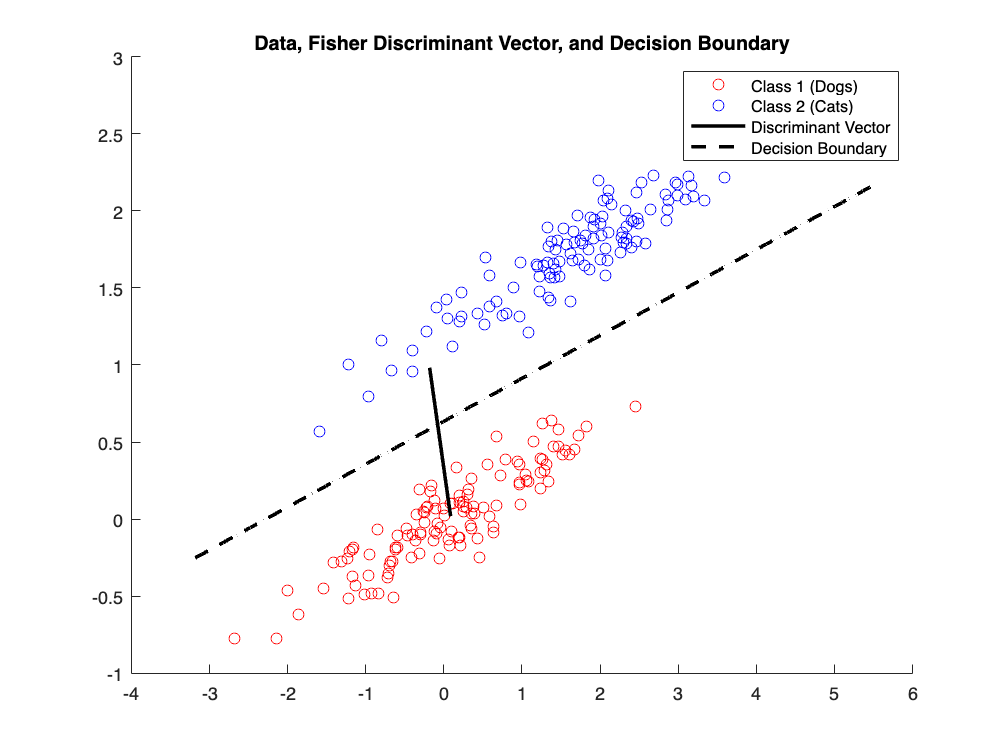

x_range = linspace(x_min, x_max, 100);
y_range = (threshold_svd - discriminant_svd(1) * x_range) / discriminant_svd(2);
figure;
scatter(data1(:, 1), data1(:, 2), 'ro'); hold on;
scatter(data2(:, 1), data2(:, 2), 'bo');
plot([mean1(1), mean1(1) + discriminant_unit(1)], [mean1(2), mean1(2) + discriminant_unit(2)], 'k-', 'LineWidth', 2); % Discriminant vector
plot(x_range, y_range, 'k--', 'LineWidth', 2); % Decision boundary
title('Data, Fisher Discriminant Vector, and Decision Boundary');
legend('Class 1 (Dogs)', 'Class 2 (Cats)', 'Discriminant Vector', 'Decision Boundary');

proj_data1 = data1 * discriminant_svd'; % Projection for class 1
proj_data2 = data2 * discriminant_svd'; % Projection for class 2
correct1 = sum(proj_data1 < threshold); % Correctly classified as class 1
correct2 = sum(proj_data2 > threshold); % Correctly classified as class 2
accuracy = (correct1 + correct2) / (N1 + N2);
fprintf('Classification accuracy using FLD: %.2f%%\n', accuracy * 100);

Classification accuracy using FLD: 99.58%


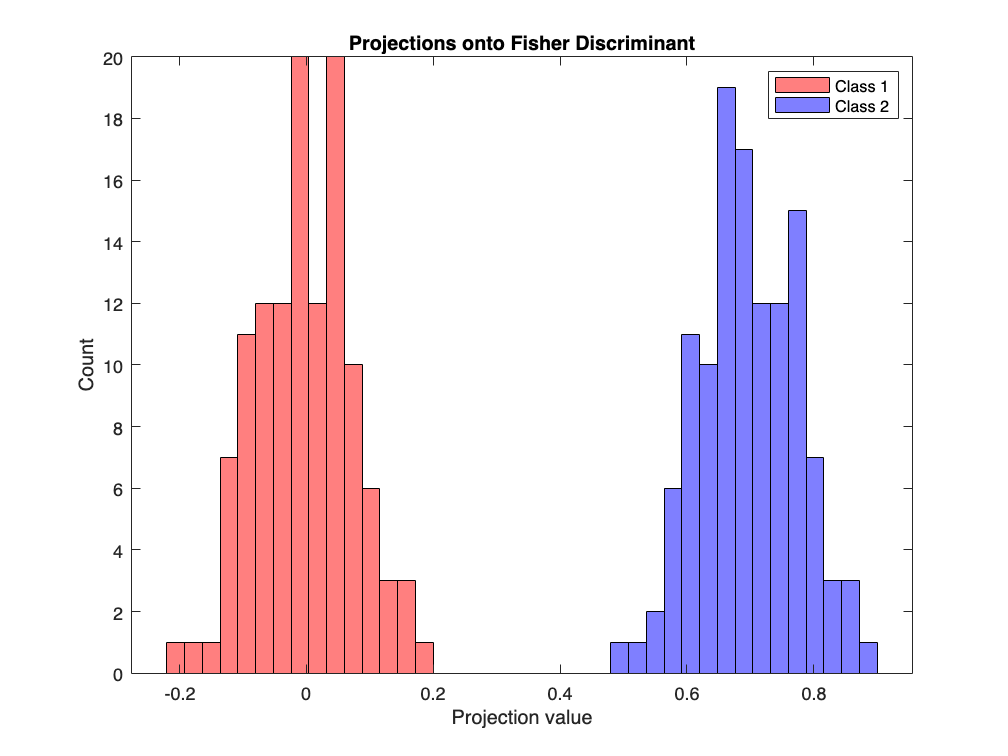

figure;
histogram(proj_data1, 15, 'FaceColor', 'r', 'FaceAlpha', 0.5);
hold on;
histogram(proj_data2, 15, 'FaceColor', 'b', 'FaceAlpha', 0.5);
title('Projections onto Fisher Discriminant');
legend('Class 1', 'Class 2');
xlabel('Projection value');
ylabel('Count');
hold off;

From two ways of computing Fisher's linear discriminant, we can see that 99.58%~100% of points are correctly being calssified.

## Part c) Ridge-Regularized Fisher Discriminant

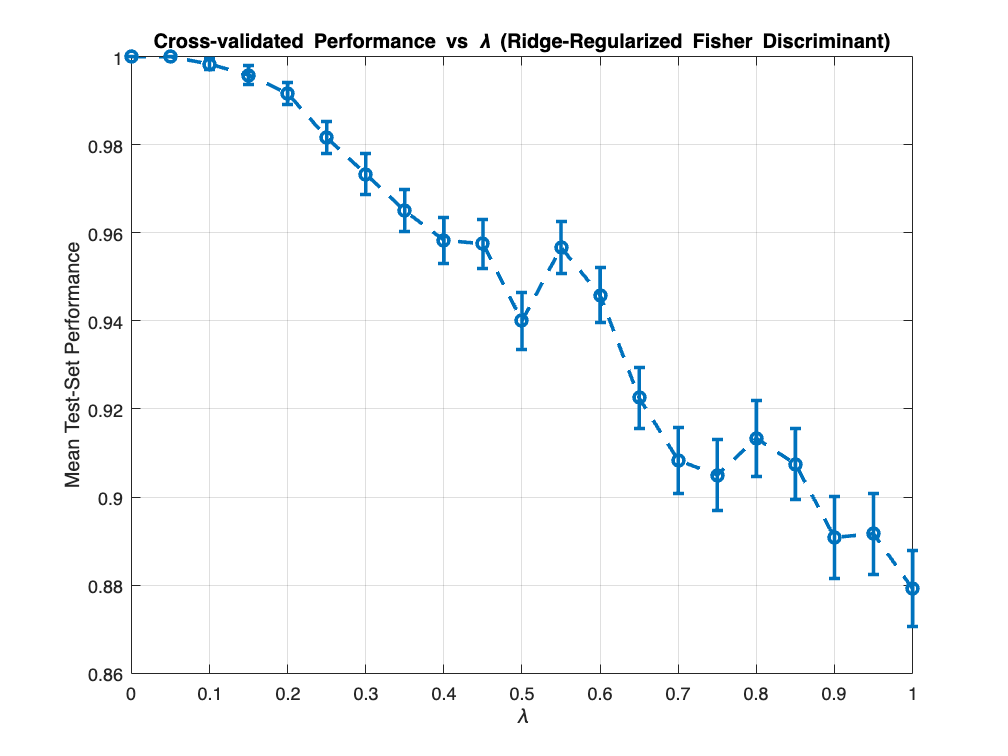

lambdas = 0:0.05:1; 
nRuns = 100;
test_fraction = 0.05;
performance = zeros(length(lambdas), nRuns);

for inx_lambda = 1:length(lambdas) %lambda
    lambda = lambdas(inx_lambda);
    
    for run_i = 1:nRuns %runs
        idx1 = randperm(N1);
        idx2 = randperm(N2);
        Ntrain1 = round((1 - test_fraction) * N1);
        Ntrain2 = round((1 - test_fraction) * N2);
        train1 = data1(idx1(1:Ntrain1), :);
        test1 = data1(idx1(Ntrain1+1:end), :);
        train2 = data2(idx2(1:Ntrain2), :);
        test2 = data2(idx2(Ntrain2+1:end), :);
        
        mean1_train = mean(train1);
        mean2_train = mean(train2);
        S1_train = cov(train1);
        S2_train = cov(train2);
        Ntrain_total = Ntrain1 + Ntrain2;
        
        poolCov_train = ((Ntrain1 - 1) * S1_train + (Ntrain2 - 1) * S2_train) / (Ntrain_total - 2);
        covEstimated = (1 - lambda) * poolCov_train + lambda * eye(size(poolCov_train));
        

        [U, S, V] = svd(covEstimated);
        S_inv = diag(1 ./ diag(S)); 
        
        %Ridge-regularized Fisher discriminant
        diff_means_ridge = (mean2_train - mean1_train)';
        discriminant_ridge = (V * S_inv * U') * diff_means_ridge;
        discriminant_ridge = discriminant_ridge';
        
        x1_est = (V * S_inv * U') * mean1_train';
        x2_est = (V * S_inv * U') * mean2_train';
        threshold_ridge = (mean2_train * x2_est - mean1_train * x1_est) / 2;
        
        dec_test1 = ((test1 * discriminant_ridge') > threshold_ridge);
        dec_test2 = ((test2 * discriminant_ridge') > threshold_ridge);
        correct1 = sum(dec_test1 == 0); %go to class 1
        correct2 = sum(dec_test2 == 1); %go to class 2
        
        performance(inx_lambda, run_i) = (correct1 + correct2) / (size(test1, 1) + size(test2, 1));
    end
end

%SEM
mean_perf = mean(performance, 2);
sem_perf = std(performance, 0, 2) / sqrt(nRuns);

figure;
errorbar(lambdas, mean_perf, sem_perf, 'o--', 'LineWidth', 2);
xlabel('\lambda');
ylabel('Mean Test-Set Performance');
title('Cross-validated Performance vs \lambda (Ridge-Regularized Fisher Discriminant)');
grid on;

%best lambda
[best_perf, best_idx] = max(mean_perf);
best_lambda = lambdas(best_idx);
disp(['Best lambda: ', num2str(best_lambda), ' with performance: ', num2str(best_perf)]);

Best lambda: 0 with performance: 1


The best lambda would be 0 since at that point perfromance is the peak.